%{
ES115 Engineering Computer Applications
Module 1 Project: Community Solar Billing Simulator

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project analyzes and compares two different community solar billing plans
to determine which plan is more cost-effective based on energy usage.
Plan A is modeled as a linear equation, while Plan B is a piecewise function
with different rates depending on usage levels. The goal is to visualize both
plans, find where they cost the same, and identify which plan is cheaper
over specific usage ranges.

Inputs (Knowns):
- Energy usage values (x) from 0 to 800 kWh
- Plan A cost model: BA(x) = 15x + 25
- Plan B cost model:
    • For x ≤ 400: BB(x) = 12x + 40
    • For x > 400: BB(x) = 14x − 760

Outputs (Unknowns):
- Monthly cost for both Plan A and Plan B
- Graph comparing both billing plans
- Usage values where both plans cost the same
- Table of usage and corresponding costs
- Ranges where each plan is more cost-effective

Engineering Workflow and Algorithms:
- Define usage range values
- Create equations for Plan A and Plan B
- Implement piecewise conditions for Plan B
- Plot both plans on the same graph
- Identify intersection points where costs are equal
- Generate a table of values for comparison
- Determine which plan is cheaper over different ranges

MATLAB Tools / Functions Used:
- plot() for graphing
- xline() for marking the breakpoint
- find() for locating intersections and comparisons
- table() for organizing data
- fprintf() and disp() for displaying results

Reflection After Completing the Project:
- I learned how to work with both linear and piecewise functions in MATLAB
  and how to compare them visually using graphs. I also got better at using
  logical indexing and the find() function to analyze data.
- If I were to do this differently, I would improve how I find the exact
  intersection point instead of relying on an approximation.
- Difficulty Rating: 5/10 — the concepts were not too hard, but applying
  piecewise conditions and comparing both plans took some thinking.
%}


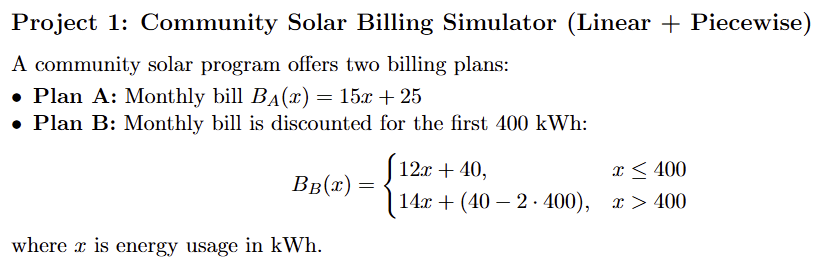

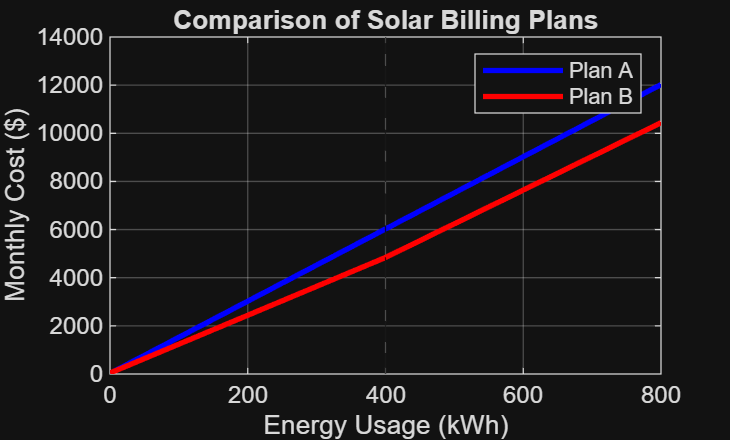

 
clear; clc; close all;

% Define usage values (kWh)
x = 0:25:800;

% Plan A (linear model)
BA = 15*x + 25;

% Plan B (piecewise model)
BB = zeros(size(x));

% For usage <= 400 kWh
BB(x <= 400) = 12*x(x <= 400) + 40;

% For usage > 400 kWh
BB(x > 400) = 14*x(x > 400) - 760;

% Plot both plans
figure;
plot(x, BA, 'b', 'LineWidth', 2); hold on;
plot(x, BB, 'r', 'LineWidth', 2);

% Show break point
xline(400, '--k');

title('Comparison of Solar Billing Plans');
xlabel('Energy Usage (kWh)');
ylabel('Monthly Cost ($)');
legend('Plan A', 'Plan B');
grid on;


% Find where plans are approximately equal
difference = BA - BB;
index = find(abs(difference) < 1e-2);

usage_equal = x(index);
cost_equal = BA(index);

disp('Where both plans cost the same (Usage, Cost):');

Where both plans cost the same (Usage, Cost):


disp([usage_equal' cost_equal']);

% Create table (first 10 rows shown)
T = table(x', BA', BB', 'VariableNames', {'Usage_kWh','PlanA','PlanB'});
disp('Sample table (first 10 rows):');

Sample table (first 10 rows):


disp(T(1:10,:));

    Usage_kWh    PlanA    PlanB
    _________    _____    _____

         0         25       40 
        25        400      340 
        50        775      640 
        75       1150      940 
       100       1525     1240 
       125       1900     1540 
       150       2275     1840 
       175       2650     2140 
       200       3025     2440 
       225       3400     2740 




disp('Sample table (first 10 rows):');

Sample table (first 10 rows):


disp(T(1:10,:));

    Usage_kWh    PlanA    PlanB
    _________    _____    _____

         0         25       40 
        25        400      340 
        50        775      640 
        75       1150      940 
       100       1525     1240 
       125       1900     1540 
       150       2275     1840 
       175       2650     2140 
       200       3025     2440 
       225       3400     2740 




% Find where Plan B is cheaper
index_B = find(BB < BA);

% Find where Plan A is cheaper
index_A = find(BA < BB);

% Display exact usage ranges
fprintf('Plan B is cheaper from %d kWh to %d kWh\n', min(x(index_B)), max(x(index_B)));

Plan B is cheaper from 25 kWh to 800 kWh


fprintf('Plan A is cheaper from %d kWh to %d kWh\n', min(x(index_A)), max(x(index_A)));

Plan A is cheaper from 0 kWh to 0 kWh
